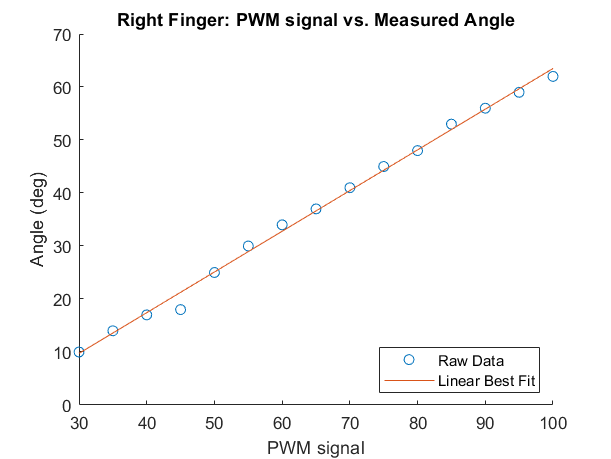

pwm = [30 35 40 45 50 55 60 65 70 75 80 85 90 95 100]; 
left_pressure = [0.43 1.38 2.34 3.36 4.9 6 7.14 8.24 9.19 9.89 10.51 11.13 11.57 12.01 12.42]; % psi 
left_flex = [2 12 22 31 40 55 66 78 87 92 98 102 105 108 112]; % unknown units but not really used
left_angle = [11 14 16 19 20 30 34 40 45 48 50 52 53 54 56]; % degrees
right_pressure = [0.8 1.57 2.45 3.18 5.34 6.29 7.39 8.27 9.15 9.78 10.66 11.35 12.01 12.45 13.08]; % psi
right_flex = [7 26 44 55 64 84 100 113 120 138 149 154 159 162 170]; 
right_angle = [10 14 17 18 25 30 34 37 41 45 48 53 56 59 62]; % degrees

figure; 
hold on
scatter(pwm, right_angle); 
plot(pwm, pwm*0.768 - 13.3); 
title('Right Finger: PWM signal vs. Measured Angle'); 
xlabel('PWM signal')
ylabel('Angle (deg)')
legend('Raw Data', 'Linear Best Fit','Location', 'southeast')
hold off 

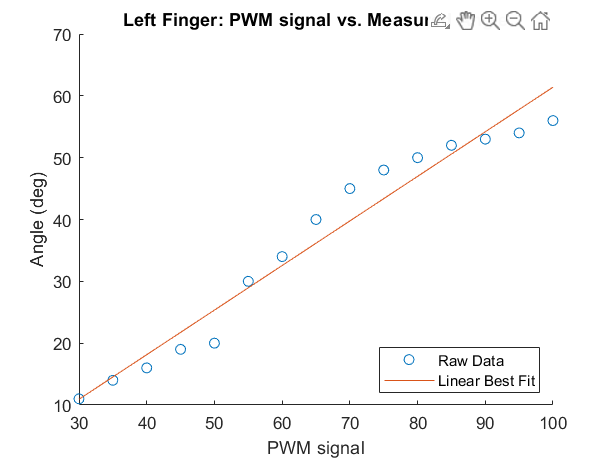


figure; 
hold on
scatter(pwm, left_angle); 
plot(pwm, pwm*0.721 - 10.7); 
title('Left Finger: PWM signal vs. Measured Angle'); 
xlabel('PWM signal')
ylabel('Angle (deg)')
legend('Raw Data', 'Linear Best Fit','Location', 'southeast')
hold off 

## Image Filtering

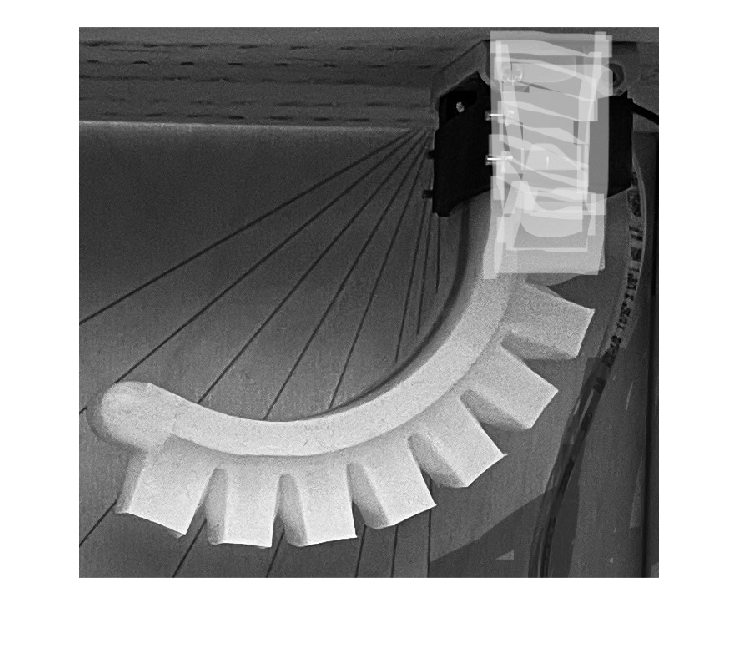

deg50 = imread("50deg-1.jpg");
imshow(deg50)

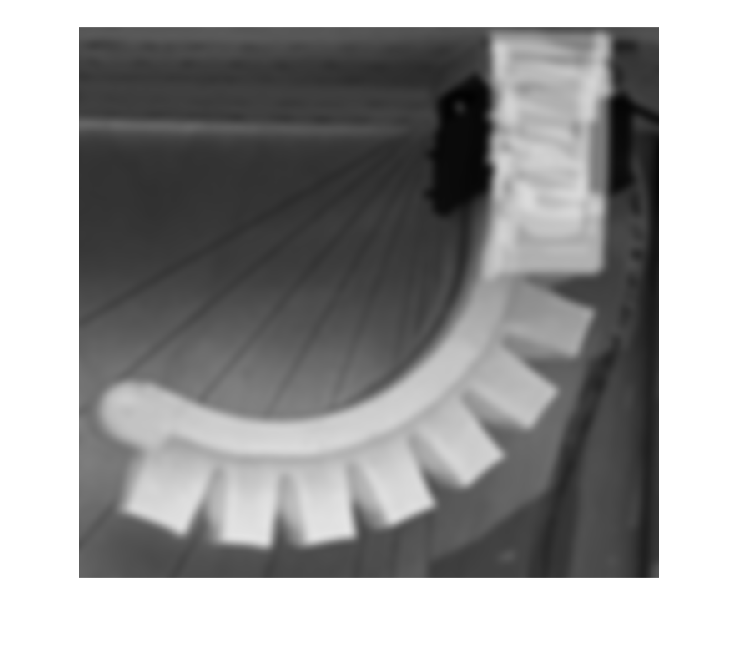

deg50_green = deg50(:,:,2); % isolate green channel but because its grayscale, should be the same
imshow(imgaussfilt(deg50_green,5)) % view blurred image with 5 pixel gaussian

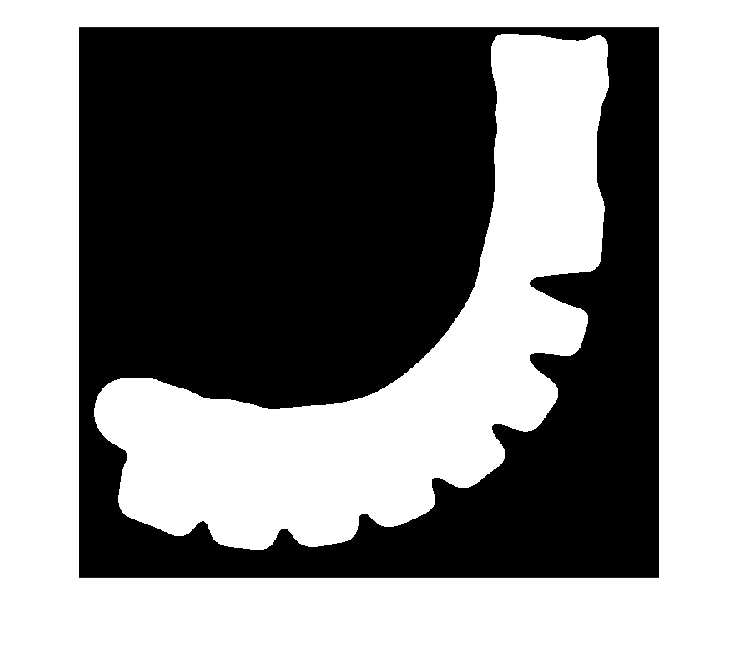

bin_deg50 = imbinarize(imgaussfilt(deg50_green,10), 0.5); % binarized image with 0.5 brightness cutoff 
imshow(bin_deg50) % show binarized image

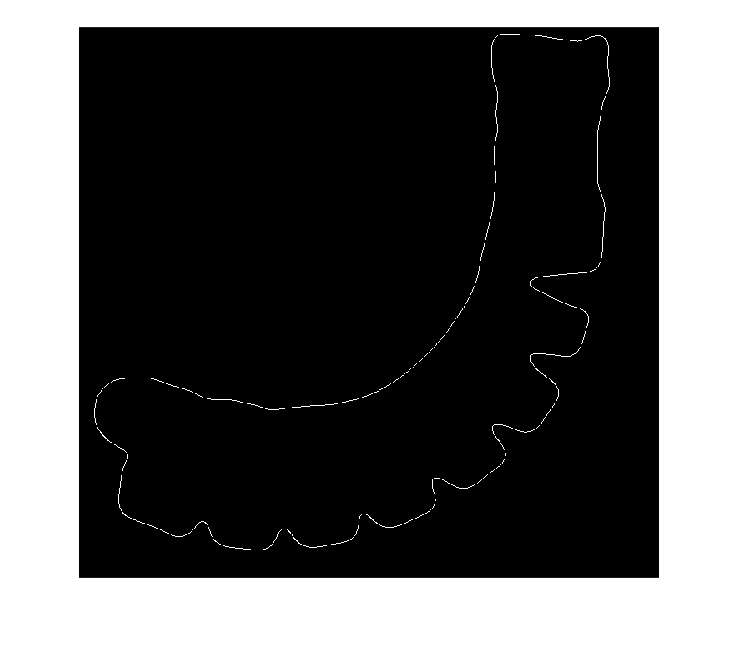

edge_of_bin50 = edge(bin_deg50); % detect the edge of the binarized image
imshow(edge_of_bin50) % show edge detected

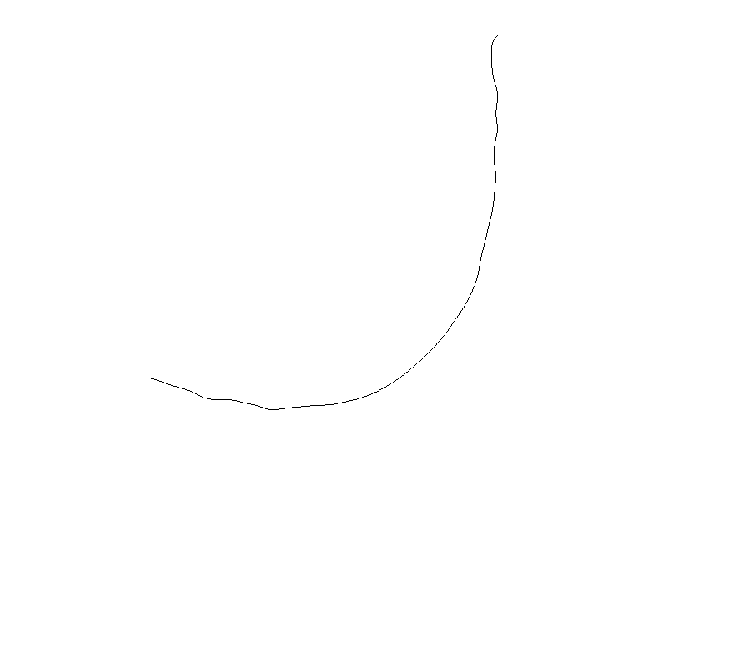


% isolate the inner curve with a copy of edge detection
copier = edge_of_bin50; 
% adjust limits to turn off specific bits
copier(:,504:end) = 0; 
copier(470:end,:) = 0;
copier(:,1:70) = 0;
% show inverted image (turn off true edges and turn on background bits)
imshow(~copier)

## Making Plots Better

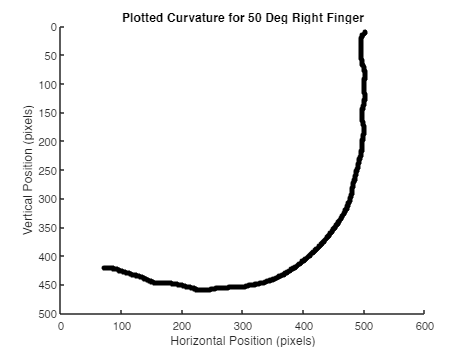

% find nonzero values for the copy 
[row_c, col_c] = find(copier);
% plot the points as a scatter plot to emulate a thicker line
figure(); 
scatter(col_c, row_c, 20,'k', 'filled')
set(gca, 'YDir','reverse')
title('Plotted Curvature for 50 Deg Right Finger')
xlabel('Horizontal Position (pixels)') 
ylabel('Vertical Position (pixels)')